# Homework 1 (Solution) 

Math 3607

Summer 2021

Tae Eun Kim

clear

## Problem 1 (Temperature Conversion)

Let $F$ and $C$ denote temperatures in (degree) Fahrenheit and Celsius, respectively. It is known that

$C = \frac{5}{9}(F-32)$.

(The factor of $5/9 = 100/180$ is due to the fact that the temperature between the freezing point and the boiling point of water is divded into 180 degrees in Farrenheit and 100 degrees in Celsius; the subtraction of 32 is to match the representations for the freezing point -- $32^\circ F = 0^\circ C$. The two are linearly related.)

I will present the script as a non-executable code block. 

## Problem 2 (Oblate Spheroid)

I will present the requested script as a single code block, so that the document is self-contained. 

format long g

Since a static pdf document is to be produced, instead of using the interactive `input` function, I will directly provide the geo-data of the Earth. 

% r1 = input('Enter equatorial radius (r1): ');
% r2 = input('Enter polar radius (r2 < r1): ');
r1 = 6378.137;
r2 = 6356.752;

Here comes the calculation using the given formulas.

gamma = acos(r2/r1);
A_exact = 2*pi*( r1^2 + ...
    r2^2/sin(gamma) * log( cos(gamma)/(1-sin(gamma)) ));
A_approx = 4*pi*( (r1+r2)/2 )^2;
disp('The surface area of the given spheroid:')

The surface area of the given spheroid:


disp(['Exact:  ', num2str(A_exact)])

Exact:  510065604.9442


disp(['Approx: ', num2str(A_approx)])

Approx: 509495321.6397


**Remarks.**

- Note that the line where `A_exact` is calculated is continued to the next line by using `...` . This is useful when you want to type in a lengthy code over multiple lines for enhanced readability.

- When `disp` or `fprintf` is called within a Live Script, it prints out outputs and disrupts the code block. I personally find this annoying and would prefer all outputs to be printed after the end of the gray code block. A workaround, for now, is to write an external script and call it in here as I demonstrated in class. Soon, we will learn about MATLAB *functions* and they can help us fix this nuiance to some degree.

## Problem 3 (Leap Year)

#### Solution 1

Consider the pseudocode provided in the lecture slides:

Below is a direct translation of the pseudocode:

year = 2021; % this year is not a leap year.
% or  year = input('Enter year: ');
msgCommon = 'Given year is a common year.';
msgLeap = 'Given year is a leap year.';

if mod(year, 4) ~= 0
    disp(msgCommon)
elseif mod(year, 100) ~= 0
    disp(msgLeap)
elseif mod(year, 400) ~= 0
    disp(msgCommon)
else
    disp(msgLeap)
end

Given year is a common year.


**Analysis.** The key reason why the code above work is due to the fact that branches of `if`-statement are visited sequentially from top to bottom and only the first branch whose condition evaluates to "true" is executed. One of the best ways to leverage this mechanism is to gradually narrow down the scope of the conditions if possible. See the Venn diagram below which schematically partitions all years into common years (light green) and leap years (light red) according to their numerical characterization.

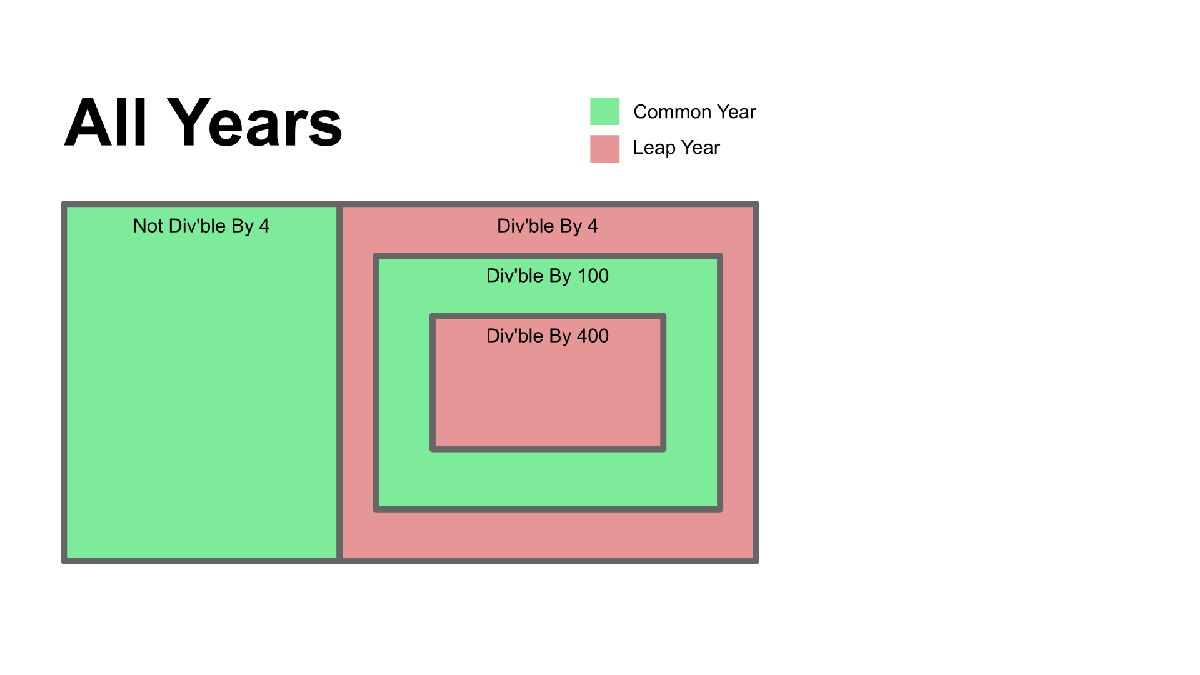

#### Solution 2

Alternately, we can utilize the alternate description of leap years given in the homework prompt, that is,

    *"In simpler terms, a non-century year is a leap year if it is divisible by 4; a century year is a leap year if it is divisible by 400."*

and write

year = 2021;
if mod(year, 100) ~= 0                  % non-century year
    if mod(year, 4) == 0                % rule for leap year
        disp(msgLeap)
    else
        disp(msgCommon)
    end
else                                    % century year
    if mod(year, 400) == 0              % rule for leap year
        disp(msgLeap)
    else
        disp(msgCommon)
    end
end

Given year is a common year.


In words, this is an example in which different rules are used for century years and non-century years.

#### Solution 3

You could piece together multiple conditions characterizing leap years using logical operators.

year = 2021;
if mod(year,4)~=0 || ( mod(year,100)==0 && mod(year,400)~=0 )
    disp(msgCommon)
else
    disp(msgLeap)
end

Given year is a common year.


## Problem 4 (3-D Coordinate Conversion)

Given the relationship between the sets of coordinates, one can derive (or recall from calculus) that


$$\begin{array}{rcl}
\rho & = & \sqrt{x^2 + y^2 + z^2} \\
\tan \theta & = & \frac{y}{x} \\
\cos \phi & = & \frac{z}{\sqrt{x^2 + y^2 + z^2}
\end{array}$$


Note that the last equation, when inverted, yields

$\phi = \arccos \frac{z}{\sqrt{x^2 + y^2 + z^2}} = \arccos \frac{z}{\rho}$,

and since the range of $\arccos$ is precisely $[0, \pi]$, it can be easily coded using the built-in `acos` function. However, since we are require to find $\theta \in [0, 2\pi)$, adjustments are called for. Below is the breakdown of possible scenarios according to the quadrant to which $(x,y)$ belongs. Ignore for now the case in which both $x$ and $y$ are zero.

- [Q1] If $x > 0$ and $y \ge 0$, then $\theta = \arctan(y/x)$.

- [Q2] If $x\le0$ and $y>0$, then $\theta = \arctan(y/x) + \pi$.

- [Q3] If $x < 0$ and $y \le 0$, then $\theta = \arctan(y/x) + \pi$.

- [Q4] If $x \ge 0$ and $y < 0$, then $\theta = \arctan(y/x) + 2\pi$.

**Note.** Suppose $y \neq 0$. Mathematically speaking, the fraction $y/x$ is not defined when $x = 0$. But MATLAB produces `Inf `or `-Inf` depending on the sign of $y$. Furthermore, the function `atan` is programmed so that it can handle these special inputs appropriately. However, when $x = y = 0$, MATLAB does the following:

0/0

ans =    NaN

atan(0/0)

ans =    NaN

So we need to treat this special case separately. How? Think geometry. If $x = y = 0$, then the point $(x,y,z) = (0, 0, z)$, *i.e.*, it lies on the $z$-axis. So

- $\rho = \sqrt{x^2 + y^2 + z^2} =\sqrt{0^2 + 0^2 + z^2}= \vert z \vert$;

- $\phi = \arccos \frac{z}{\vert z \vert} = \arccos (\pm 1)$, which is 0 or $\pi$ depending on the sign of $z$;

- $\theta$ is immaterial and can be any number; we will simply set $\theta = 0$. 

Now let's encode all these details. Instead of making it interactive using `input`, I will simply provide some data myself $(x,y,z) = (0, 3, -1)$ for the sake of simplicity. As mentioned earlier, after learning about functions and live functions (Lecture 5), we should be able to do this nicely.

x = 0; y = 3; z = -1;
% x = input('Enter x: ');
% y = input('Enter y: ');
% z = input('Enter z: ');
fprintf('Given input: (x,y,z) = (%g, %g, %g)\n', x, y, z)

Given input: (x,y,z) = (0, 3, -1)


rho = sqrt(x^2 + y^2 + z^2);
phi = acos(z/rho);
if x > 0 && y >= 0      % 1st quadrant
    theta = atan(y/x);
elseif x <=0 && y > 0   % 2nd quadrant
    theta = atan(y/x) + pi;
elseif x < 0 && y <=0   % 3rd quadrant
    theta = atan(y/x) + pi;
elseif x >=0 && y < 0   % 4th quadrant
    theta = atan(y/x) + 2*pi;
else                    % (x,y) = (0,0)
    theta = 0;
end
disp(' ')

fprintf('  rho:   %10.4f\n', rho)

  rho:       3.1623


fprintf('  phi:   %10.4f\n', phi)

  phi:       1.8925


fprintf('  theta: %10.4f\n', theta)

  theta:     4.7124


**Exercise.** As suggested in the lecture slides, do this problem using `atan2` instead of `atan`. Be sure to check out how MATLAB's `atan2` treats the special case of $x=y=0$.

## Problem 5 (Game of 3-Stick)

We can use `rand` to simulate picking three sticks with random lengths between 0 and 1.

For this triple to be sides of a triangle, the length of **any** one must not exceed the sum of the other two, that is, all of the following must be true:

- `a < b + c`

- `b < a + c`

- `c < a + b`

Let's simulate a single game.

a = rand();
b = rand();
c = rand();
if (a<b+c) && (b<a+c) && (c<a+b)
    disp('You won!')
else
    disp('You lost.')
end

You won!


To simulate multiple games, you will embed the code above within a `for`-loop. In addition, we will keep track of the number of games won rather than displaying win/loss messages.

nrWins = 0;
nrGames = 20;
for j = 1:nrGames
    a = rand(); b = rand(); c = rand();
    if (a<b+c) && (b<a+c) && (c<a+b)
        nrWins = nrWins + 1;
    end
end
nrWins

nrWins =     10

nrGames

nrGames =     20

Note the deletion of the else-block since we need not do anything in this context. 

**Final Version. **Now that we know that the script above works with a modest number of games, let's increase it to one million as requested by the problem. In addition, let's format outputs nicely using `fprintf` or `disp`.

nrWins = 0;
nrGames = 1e6;   % one million games
for j = 1:nrGames
    a = rand();
    b = rand();
    c = rand();
    if (a<b+c) && (b<a+c) && (c<a+b)
        nrWins = nrWins + 1;
    end
end
pWin = nrWins/nrGames; % prob. of winning a game
fprintf('Games won:     %8d\n', nrWins)

Games won:       498964


fprintf('Games played:  %8d\n', nrGames)

Games played:   1000000


fprintf('Winning ratio: %8.4f\n', pWin)

Winning ratio:   0.4990


## **Extra: Solving Problem 5 Using New Techniques**

The problem was assigned when we did not know about *arrays*. But by the time this solution is posted, we all do. Since Exam 1 is fast approaching, let's try to work this out using arrays for practice. 

**Step 1.** Simulate multiple games using `rand` function.

format short
nrGames = 20;
sticks = rand(3, nrGames)

sticks =     0.2292    0.4393    0.9400    0.0758    0.8350    0.4749    0.5118    0.4040    0.9521    0.1845    0.9971    0.5406    0.2412    0.9603    0.1087    0.8083    0.4782    0.7786    0.3681    0.4525
    0.4030    0.0306    0.8247    0.6924    0.1451    0.1285    0.3924    0.0483    0.7474    0.5188    0.3411    0.2462    0.2270    0.7163    0.2049    0.3631    0.0134    0.5837    0.1860    0.8065
    0.7839    0.1990    0.7801    0.7692    0.7925    0.2990    0.8676    0.6438    0.7001    0.1442    0.0926    0.2940    0.4290    0.8617    0.5788    0.7412    0.6347    0.8095    0.7585    0.2591


Each column corresponds to a single game. The matrix `sticks` holds the information of 20 games.

**Step 2.** Generate an auxiliary matrix incorporating the "triangle" conditions. 

I will create an auxiliary matrix `A` (for analysis) whose $j$th columns contain the following information:

- `A(1,j) = -sticks(1,j) + sticks(2,j) + sticks(3,j)`

- `A(2,j) =  sticks(1,j) - sticks(2,j) + sticks(3,j)`

- `A(3,j) =  sticks(1,j) + sticks(2,j) - sticks(3,j)`

In this setup, the $j$th game is won if and only if all entries of the $j$th column of `A` are positive. 

A = zeros(size(sticks));
A(1,:) = -sticks(1,:) + sticks(2,:) + sticks(3,:);
A(2,:) =  sticks(1,:) - sticks(2,:) + sticks(3,:);
A(3,:) =  sticks(1,:) + sticks(2,:) - sticks(3,:);
A

A =     0.9577   -0.2097    0.6648    1.3859    0.1026   -0.0474    0.7482    0.2881    0.4954    0.4784   -0.5634   -0.0004    0.4148    0.6176    0.6751    0.2960    0.1698    0.6146    0.5764    0.6131
    0.6101    0.6077    0.8954    0.1526    1.4825    0.6454    0.9870    0.9994    0.9048   -0.1900    0.7486    0.5883    0.4432    1.1057    0.4825    1.1863    1.0995    1.0045    0.9406   -0.0949
   -0.1518    0.2709    0.9846   -0.0010    0.1876    0.3043    0.0366   -0.1915    0.9995    0.5591    1.2455    0.4928    0.0392    0.8149   -0.2652    0.4303   -0.1430    0.5528   -0.2044    0.9999


**    Sidenote. **The matrix `A` can be constructed by a single statement

    This is a triumphant moment in which the understanding of matrix multiplication shines in progamming! (Make sure you understand why this works!)

Now, I will replace positive entries of `A` by 1 and non-positive (that is, less than or equal to zero) entries by 0.

A(  A>0 ) = 1;   % same as A( find( A>0) ) = 1, but more efficient
A( A<=0 ) = 0;   % same as A( find(A<=0) ) = 0, but more efficient
A

A =      1     0     1     1     1     0     1     1     1     1     0     0     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0
     0     1     1     0     1     1     1     0     1     1     1     1     1     1     0     1     0     1     0     1


**Step 3.** Identify the games won.

Finally, generate a row vector by sum all elements of `A` along columns:

sumA = sum(A)

sumA =      2     2     3     2     3     2     3     2     3     2     2     2     3     3     2     3     2     3     2     2


The elements that are equal to 3 correspond to the games won!

**Full script (Vectorized).**

Let's put all together.

nrGames = 1e6;
sticks = rand(3, nrGames);
A = [-1 1 1; 1 -1 1; 1 1 -1] * sticks;
A( A >0 ) = 1;
A( A<=0 ) = 0;
sumA = sum(A);
nrWins = length(find(sumA==3));
pWin = nrWins/nrGames; % prob. of winning a game
fprintf('Games won:     %8d\n', nrWins)

Games won:       499822


fprintf('Games played:  %8d\n', nrGames)

Games played:   1000000


fprintf('Winning ratio: %8.4f\n', pWin)

Winning ratio:   0.4998
